# Lab A: System of Linear Equations

## Part 1 

### **Practice problem**

Calculate the solution of the linear system of equations using Gauss Elimination method. Use the matrix operations from the pre-lab material. 


$$\begin{array}{l}
5x+15y+56z=35\\
-4x-11y-41z=-26\\
-x-3y-11z=-7
\end{array}$$


a = [5 15 56 35; -4 -11 -41 -26; -1 -3 -11 -7]

a =      5    15    56    35
    -4   -11   -41   -26
    -1    -3   -11    -7


a(1,:) = a(1,:)/5

a =     1.0000    3.0000   11.2000    7.0000
   -4.0000  -11.0000  -41.0000  -26.0000
   -1.0000   -3.0000  -11.0000   -7.0000


a(2,:) = a(2,:) + 4 * a(1,:)

a =     1.0000    3.0000   11.2000    7.0000
         0    1.0000    3.8000    2.0000
   -1.0000   -3.0000  -11.0000   -7.0000


a(3,:) = a(3,:) + a(1,:)

a =     1.0000    3.0000   11.2000    7.0000
         0    1.0000    3.8000    2.0000
         0         0    0.2000         0


a(3,:) = 5*a(3,:)

a =     1.0000    3.0000   11.2000    7.0000
         0    1.0000    3.8000    2.0000
         0         0    1.0000         0


a(1,:) = a(1,:) - 3*a(2,:)

a =     1.0000         0   -0.2000    1.0000
         0    1.0000    3.8000    2.0000
         0         0    1.0000         0


a(1,:) = a(1,:) + 0.2*a(3,:)

a =     1.0000         0    0.0000    1.0000
         0    1.0000    3.8000    2.0000
         0         0    1.0000         0


a(2,:) = a(2,:) - 3.8*a(3,:)

a =     1.0000         0    0.0000    1.0000
         0    1.0000    0.0000    2.0000
         0         0    1.0000         0


**STUDENT ANSWER:**

x = 1, y = 2, z = 0 

## Part 2

### Example

Solve the system of linear equations given below:

[https://www.mathworks.com/help/symbolic/solve-a-system-of-linear-equations.html](https://www.mathworks.com/help/symbolic/solve-a-system-of-linear-equations.html)

Solve $\textrm{Ax}=b\;\textrm{for}\;x$.


$$\begin{array}{l}
2x+y+z=2\\
-x+y-z=3\\
x+2y+3z=-10
\end{array}$$
 

A = [2, 1, 1;-1, 1, -1;1, 2, 3]

A =      2     1     1
    -1     1    -1
     1     2     3


B = [2;3;-10]

B =      2
     3
   -10


X = linsolve(A, B)

X =      3
     1
    -5


Y = A\B

Y =      3
     1
    -5


### ------------------------

### Practice problem

Solve the system of linear equations from the Problem 1 using the above functions. 

a = [5 15 56; -4 -11 -41; -1 -3 -11]

a =      5    15    56
    -4   -11   -41
    -1    -3   -11


b = [35; -26; -7]

b =     35
   -26
    -7


x = linsolve(a,b)

x =     1.0000
    2.0000
    0.0000


y = a\b

y =     1.0000
    2.0000
    0.0000


**STUDENT ANSWER**

x = 1, y = 2, z = 0

## Part 3

### Example

Solving a system of linear equations using the inverse method (this will be covered later in the course lectures)

% defines a 3x3 matrix with random integers
A = randi(3, 3)

A =      3     1     3
     2     2     3
     3     3     2


% gives the inverse of the matrix A
inv(A)

ans =     0.5000   -0.7000    0.3000
   -0.5000    0.3000    0.3000
    0.0000    0.6000   -0.4000


% gives the rank of the matrix
rank(A)

ans = 3

% gives the structural rank - useful when a number of elements are zeros,
% used for sparse matrix
sprank(A)

ans = 3

% example with sprank
C = sparse([1, 2, 3], [1, 2, 4], [10, 20, 30], 5, 5)

C =    (1,1)       10
   (2,2)       20
   (3,4)       30


sprank(C)

ans = 3

### ------------------------

### Practice problem

1. Calculate the solution of the system of linear equations given in Problem 2 using the inverse function as: $x=\left(A^{-1} \right)b$

A = [2, 1, 1;-1, 1, -1;1, 2, 3];
B = [2;3;-10];
x = inv(a)*b

x =     1.0000
    2.0000
         0


## Part 4

Using a "for" loop to iteratively perform operations

Resource for "for" loop : [https://www.mathworks.com/help/matlab/ref/for.html](https://www.mathworks.com/help/matlab/ref/for.html)

### Example

Here are a few methods to perform "for" loops:

-     Run with each next element. 

                    for i = 1:10

                            k = i^2

                    end

        2.     Run with a known difference

                    for i = 10:-0.5:1 

                             k = i^2

                    end

        3.     Run over a vector

                    for i = [1, 2, 3, 4, 5]

                            k = i^2

                    end

### ------------------------

### Practice problem

    1. Using a "for" loop, calculate the function x^2+x+1 for x in range 1 to 100. Plot the result. 

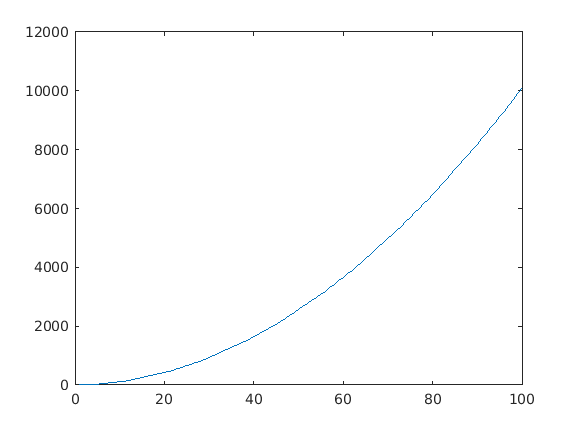

x = [];
y = [];
for i = 1:100
    x(i,1) = i;
    y(i,1) = i^2+i+1;
end
plot(x,y)